# Lab 1 - Sampling and Aliasing - R4, R5, R6

## 0. Init

clear;

## 4.

% Upload sound file
[x, Fs] = audioread('romanza_pe.wav');
Fs

Fs = 44100

% play sampled sound
soundsc(x, Fs);

% stop sound
clear sound

% Set window length
N= 4*[8 50 100 200 300 400];  
% Compute and display spectrogram of x 
figure();
for i = 1:6
    subplot(3,2,i);
    spectrogram(x(1:Fs*15), hann(N(i)), 3*N(i)/4, 4*N(i), Fs, 'yaxis');
end

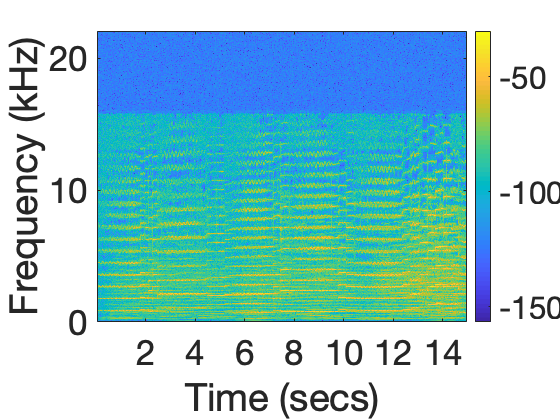

N = 4*600;
figure();
spectrogram(x(1:Fs*15), hann(N), 3*N/4, 4*N, Fs, 'yaxis');
set(gca,'FontSize',35);

**R4.a)   **From the plots above seems that the best window value is $N=1200$. For window sizes below and above $N=1200
$ the spectrogram is not as sharp. It is very interesting to notice that it is possible to identify the different harmonics of the violin heard simultaneously. These hamonics correnpond to multiples of a fundamental frenquency of the key played.

## 5.

% Fs/5 sampling -> y
y = x(1:5:length(x));
Fs_y = Fs/5

Fs_y = 8820

% play sampled sound
soundsc(y, Fs_y);

% stop sound
clear sound

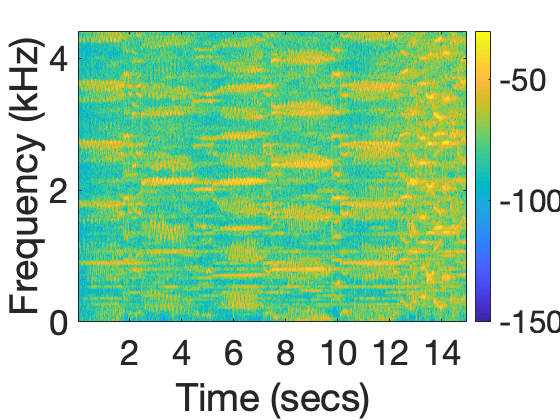

N = 4*600/5;
figure();
spectrogram(y(1:Fs_y*15), hann(N), 3*N/4, 4*N, Fs_y, 'yaxis');
set(gca,'FontSize',35);

**R5.a) **The lower frequencies of the original song appear to be played as they were in the original audio signal. However, the higher frequencies are no longer heard and, as displayed in the spretrogram, they are distorted and played as lower frequencies. It is still possible to identify some harmonics of the violin, but they are superimposed with the distorted higher frequencies. Note that there are not any frequencies in the signal $y(n)$ above $f \approx 4.5 \mathrm{kHz}$, which, as expected form the Sampling Theorem, corresponds to half the sampling frequency $f_s/2 = 4.41 \mathrm{kHz}$. Other interesting phenomenon is that each time that a frequency is increasing in the original audio and is above $f \approx 4.5 \mathrm{kHz}$ it appears that the frequency played by signal $y(n)$ is oscilating in time, instead of increasing. This phenomenom is due to the distortion of the original frequencies wich are maped, when sampled in $y(n)$, to lower frequencies into the range $[0;f_s/2]$. This map oscilates between the boundary values of this range as the frequency of the original signal increases. This is easily seen in a spectrograp considering the chirp considered in 1. sampled at $f_s = 1 \mathrm{kHz}$, as seen below

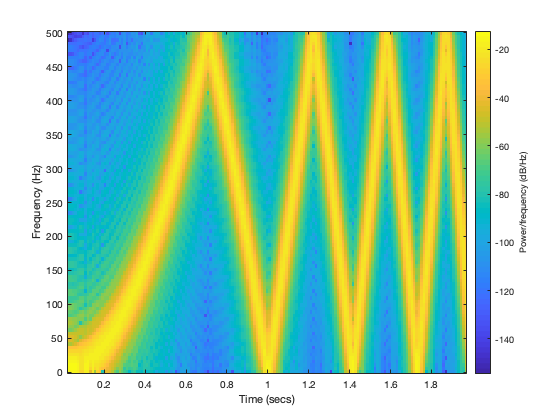

% Continuos time chirp:
% x_c = cos[2*pi*(1/3*k2*t^3 + 1/2*k1*t^2 + F0*t + phi0)]
% Define constants
k1 = 0;
k2 = 1000;
F0 = 0;
phi0 = 0;
%=> x_c = cos[2*pi*1/3*k2*t^3]
% Sampling of x_c -> x
SPS_y = 1000;
T = [0 2];
t = T(1):1/SPS_y:T(2);
y = cos(2*pi*(1/3*k2*t.^3 + 1/2*k1*t.^2 + F0*t + phi0));
% Adjust window size
N_y = 4*12; 
% Compute and display spectrogram of y
figure();
spectrogram(y, hann(N_y), 3*N_y/4, 4*N_y, SPS_y, 'yaxis');

**6.**

% 100th order Low-pass FIR filter
xf = filter(fir1(100, 0.2), 1, x);
% Cut-off freqeuncy (Hz)
fc = 0.2*pi/(2*pi*1/Fs)

fc = 4410

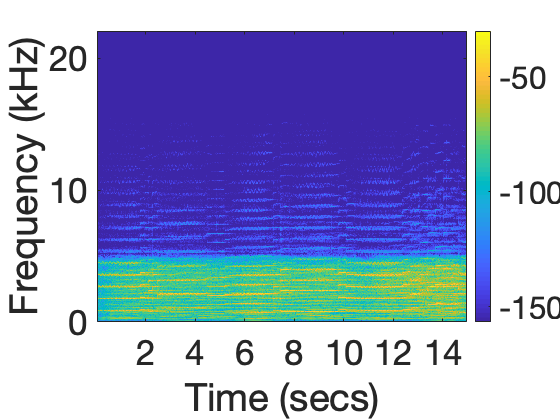

N = 4*600;
figure();
spectrogram(xf(1:Fs*15), hann(N), 3*N/4, 4*N, Fs, 'yaxis');
set(gca,'FontSize',35);

% Fs/5 sampling -> y
yf = xf(1:5:length(x));
Fs_yf = Fs/5;

% play sampled sound
soundsc(yf, Fs_yf);

% stop sound
clear sound

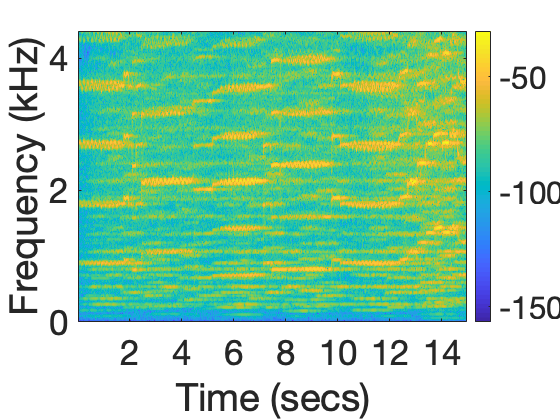

N = 4*600/5;
figure();
spectrogram(yf(1:Fs_y*15), hann(N), 3*N/4, 4*N, Fs_y, 'yaxis');
set(gca,'FontSize',35);

**R6.a) **Hearing the sampling of the filtered signal and comparing it with the original song, it is evident that the higher frequencies are no longer heard. In fact, given that the filter has a high order and cut-off frequency of $f_c = 4.41\mathrm{kHz}$, it is expected that frequencies above $f_c = 4.41\mathrm{kHz}$ are highly atenuated and no longer heard. Also, note that the cut-off frequency of the low-pass FIR filter corresponds to the highest frequency in the sampled signal in 5. and 6.. However, whereas in 5. the signal that was sampled ($x(n)$) contained frequencies higher that half the sampling frequency, in 6. the signal that was sampled ($x_f(n)$) does not because they were atenuated beforehand by the FIR filter. For this reason, while in 5. $y(n)$ sounds very distorted, the sound played by $y_f(n)$ does not. In fact, the phenomenon of the ocilating frequency caused by the sampling is no longer heard and the sound is much more pleasent. This is also noticeable comparing the sprectrographs of 5. and 6.. In fact, while in the spectrograph in 5. the low frequency harmonics are superimposed with the distorted high frequency harmonics of the original song, in the spectrograph in 6. the low frequency harmonics are easily detected and are not distorted. These hamonics correnpond to multiples of a fundamental frenquency of the key played. Thus, even though the original high frequency harmonics are atenuated, it is possible to hear the same keys without distortion. 

For this reason, supose that it is necessary to sample a signal at a given sample frenquecy $f_s$. But $f_s$ is greater than half the highest frequency of that signal. Then, the original signal should be filtered before being sampled, with a low pass-filter with cut-off frequency of $f_s/2$, in order to avoid distortion and consequent phenomena. 